# Evaluación: Localización de un robot diferencial

**Paola Rojas Domínguez A01737136**

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

## Ejercicio 1

### Tiempo

Se definen los parámetros temporales del experimento: tiempo de intregración por paso (`ts`), y el numero de pasos (N)

ts = 1;
N = 12;

### Pose inicial

Se define la coordenada y orientación inicial del robot

x = -1;
y = -5;
theta = deg2rad(0);

### Pasos

Se establece el historial de pasos descrito en el ejercicio

pasos = [
    1.0,   0.0;
    0.0,  pi/3;
    1.0,   0.0;
    0.0,  pi/3;
    1.0,   0.0;
    0.0,  pi/3;
    1.0,   0.0;
    0.0,  pi/3;
    1.0,   0.0;
    0.0,  pi/3;
    1.0,   0.0;
    0.0,  pi/3
];

### Bucle de simulación

El bucle `for` que recorre todas las muestras temporales. Se establecen las velocidad don la matriz de pasos.

for k = 1:N
    v = pasos(k, 1);   % velocidad lineal
    w = pasos(k, 2);   % velocidad angular

En cada iteración, se actualizan las cordenadas (x,y) y la orientación theta del robot utilizando integración numérica con el método de Euler. 

    x = x + v * cos(theta) * ts;
    y = y + v * sin(theta) * ts;
    theta = theta + w * ts;

#### Poses

Finalmente, imprimimos las poses del robot en cada paso

    fprintf('Paso %2d: x = %.3f, y = %.3f, θ = %.2f°\n', k, x, y, rad2deg(theta));
end

Paso  1: x = 0.000, y = -5.000, θ = 0.00°
Paso  2: x = 0.000, y = -5.000, θ = 60.00°
Paso  3: x = 0.500, y = -4.134, θ = 60.00°
Paso  4: x = 0.500, y = -4.134, θ = 120.00°
Paso  5: x = 0.000, y = -3.268, θ = 120.00°
Paso  6: x = 0.000, y = -3.268, θ = 180.00°
Paso  7: x = -1.000, y = -3.268, θ = 180.00°
Paso  8: x = -1.000, y = -3.268, θ = 240.00°
Paso  9: x = -1.500, y = -4.134, θ = 240.00°
Paso 10: x = -1.500, y = -4.134, θ = 300.00°
Paso 11: x = -1.000, y = -5.000, θ = 300.00°
Paso 12: x = -1.000, y = -5.000, θ = 360.00°


% Pose final
fprintf('\nPose final del robot:\n'); fprintf('x = %.3f, y = %.3f, θ = %.2f°\n', x, y, rad2deg(theta));


Pose final del robot:
x = -1.000, y = -5.000, θ = 360.00°


## Ejercicio 2

### **Parámetros del robot**

Se definen las dimensiones físicas del robot, necesarias para calcular las velocidades lineales y angulares a partir de las velocidades de las ruedas.

r = 0.1;     % Radio de rueda
L = 0.4;     % Distancia entre ruedas

### **Velocidades angulares de las ruedas**

Se asignan las velocidades angulares (rad/s) de cada rueda para la simulación. Estas determinan cómo se mueve el robot en cada instante de tiempo.

wR = [4.582; 4.773; 5.291; 5.960; 6.490; -1.168; -1.364; 5.960; 5.291; 4.773;
      4.582; 4.773; 5.291; 5.960; 6.490; 6.686; 6.490; 5.960; 5.291; 4.773; 4.582];

wL = [1.701; 2.353; 3.676; 4.856; 5.618; 13.735; 13.472; 4.856; 3.676; 2.353;
       1.701; 2.353; 3.676; 4.856; 5.618; 5.881; 5.618; 4.856; 3.676; 2.353; 1.701];

### **Cálculo de velocidades de referencia**

A partir de las velocidades angulares de cada rueda, se obtienen las velocidades lineales `u0` y angulares `w0` del robot, usando el modelo cinemático de un robot diferencial.

u0 = (r/2) .* (wR + wL);
w0 = (r/L) .* (wR - wL);

### **Tiempo**

Se define el nuevo tiempo de muestreo y se interpola para obtener un mayor detalle temporal en la simulación. Esto permite visualizar el comportamiento del robot con más precisión.

ts = 0.1;                        
t_original = 0:1:(length(u0)-1); 
t = 0:ts:t_original(end);  

% Interpolación para aumentar la resolución temporal
u = interp1(t_original, u0, t, 'linear');
w = interp1(t_original, w0, t, 'linear');

N = length(u);

### **Condiciones iniciales**

Se inicializa la posición y orientación del robot en el origen. También se inicializan los vectores para almacenar la evolución de estas variables.

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

x1(1) = 0;    
y1(1) = 0;    
phi(1) = 0;   

### **Punto de control**

Se definen vectores para registrar la trayectoria del punto de control del robot (el centro del eje entre ruedas).

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1); 
hy(1) = y1(1); 

### **Bucle de simulación**

En cada paso de tiempo se actualiza la orientación y posición del robot usando el método de integración de Euler, a partir de las velocidades interpoladas.

for k=1:N 
    phi(k+1)=phi(k)+w(k)*ts; 
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    x1(k+1)=x1(k) + xp1*ts ; 
    y1(k+1)=y1(k) + yp1*ts ; 
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
end

### **Resultados**

Se imprime el resultado de cada paso de tiempo, incluyendo velocidades y posición/orientación del robot.

for k = 1:N
    fprintf('t(s) = %-10.3f | v(m/s) = %-10.3f | w(rad/s) = %-10.3f | x(m) = %-10.3f | y(m) = %-10.3f phi(rad) = %-10.3°f\n', ...
        t(k), u(k), w(k), x1(k), y1(k), rad2deg(phi(k)));
end

t(s) = 0.000      | v(m/s) = 0.314      | w(rad/s) = 0.720      | x(m) = 0.000      | y(m) = 0.000      phi(rad) = t(s) = 0.100      | v(m/s) = 0.318      | w(rad/s) = 0.709      | x(m) = 0.031      | y(m) = 0.002      phi(rad) = t(s) = 0.200      | v(m/s) = 0.323      | w(rad/s) = 0.697      | x(m) = 0.063      | y(m) = 0.007      phi(rad) = t(s) = 0.300      | v(m/s) = 0.327      | w(rad/s) = 0.686      | x(m) = 0.094      | y(m) = 0.014      phi(rad) = t(s) = 0.400      | v(m/s) = 0.331      | w(rad/s) = 0.674      | x(m) = 0.126      | y(m) = 0.023      phi(rad) = t(s) = 0.500      | v(m/s) = 0.335      | w(rad/s) = 0.663      | x(m) = 0.157      | y(m) = 0.034      phi(rad) = t(s) = 0.600      | v(m/s) = 0.339      | w(rad/s) = 0.651      | x(m) = 0.188      | y(m) = 0.047      phi(rad) = t(s) = 0.700      | v(m/s) = 0.344      | w(rad/s) = 0.640      | x(m) = 0.218      | y(m) = 0.063      phi(rad) = t(s) = 0.800      | v(m/s) = 0.348      | w(rad/s) = 0.628      | x(m) = 0.247  

### **Simulación 3D**

Se configura una escena en 3D donde se observa el movimiento del robot en el plano XY. Se utiliza una figura gráfica que se actualiza en cada iteración del bucle para animar la trayectoria del robot.

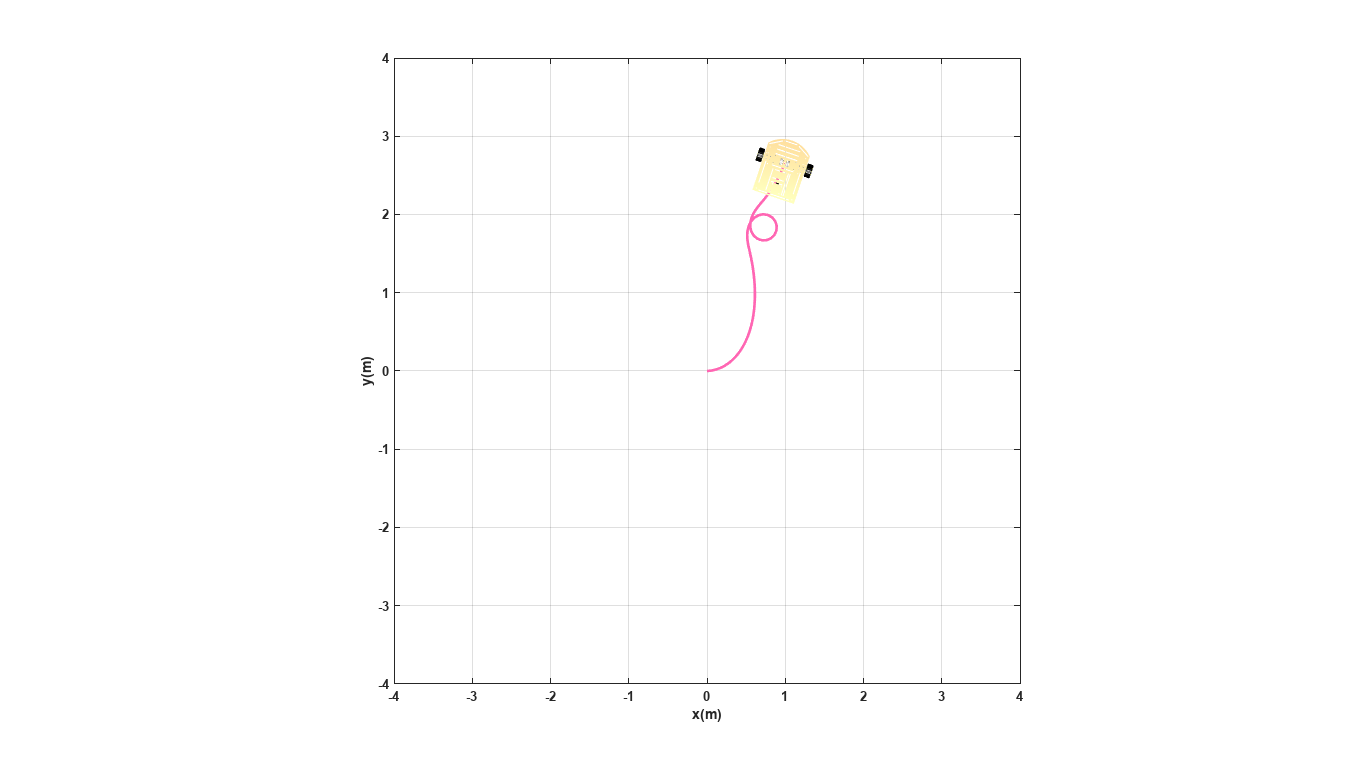

scene=figure; 
set(scene,'Color','white'); 
set(gca,'FontWeight','bold') ;
sizeScreen=get(0,'ScreenSize'); 
set(scene,'position',sizeScreen); 
camlight('headlight'); 
axis equal; 
grid on; 
box on; 
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); 
view([0 90]); 
axis([-4 4 -4 4 0 2]); 

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

step=1; 

for k=1:step:N
    delete(H1);    
    delete(H2);
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'Color', [1 0.4 0.7],'lineWidth',2);
    pause(ts);
end

### **Gráficas**

Se visualizan las velocidades de referencia del robot (lineal y angular) y su evolución temporal en posición (x, y) y orientación (phi).

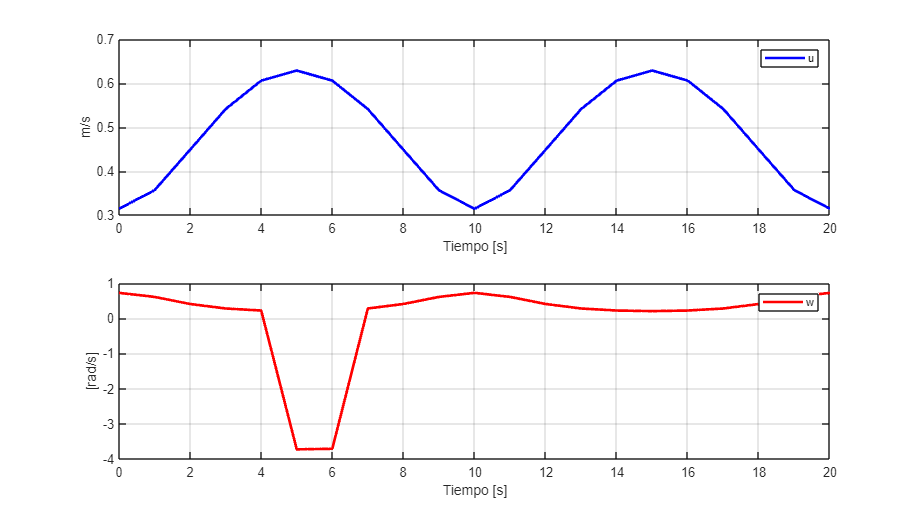

graph=figure;  
set(graph,'position',sizeScreen); 

subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

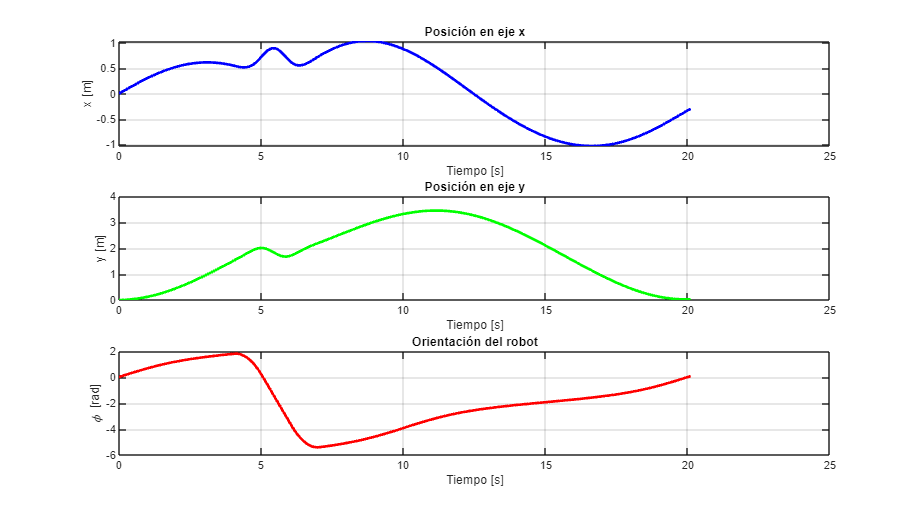

figure;
set(gcf,'position',sizeScreen); 

subplot(3,1,1)
plot((0:N)*ts, x1, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Posición en eje x');
grid on;

subplot(3,1,2)
plot((0:N)*ts, y1, 'g', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Posición en eje y');
grid on;

subplot(3,1,3)
plot((0:N)*ts, phi, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('\phi [rad]');
title('Orientación del robot');
grid on;

## Ejercicio 3

### Velocidades de referencia

En esta simulación, el robot se mueve con una velocidad lineal constante de 4 m/s mientras gira continuamente con una velocidad angular constante de 1 rad/s. Este tipo de movimiento genera una trayectoria circular, lo que permite observar el comportamiento del robot al combinar traslación uniforme con una rotación sostenida.

u = 20*ones(1, 640);
w = 1*ones(1, 640);

### Tiempo

A continuación, se establecen los parámetros temporales. El número de muestras `N` se obtiene a partir de la longitud del vector `u`, mientras que el tiempo de muestreo se define como `ts = 0.01` segundos. El vector de tiempo `t` se genera con una distribución lineal.

N = length(u);
tf = N*2;
ts = 0.01;
t = linspace(0, ts, N);

### Condiciones iniciales

Las condiciones iniciales del robot se fijan en el origen del plano, con orientación cero. Los vectores `x1`, `y1` y `phi` representan respectivamente la posición en el eje X, el eje Y y la orientación del robot a lo largo de toda la simulación.

x1 = zeros (1,N+1);
y1 = zeros (1,N+1);
phi = zeros(1, N+1);

Asignamos los valores iniciales, correspondientes a la coordenada de inicio, explícitamente en la primera posición de cada vector. 

x1(1) = 0;
y1(1) = -20;
phi(1) = 0;

### Punto de control

También se inicializan los vectores `hx` y `hy` que almacenarán la trayectoria del punto de control del robot (que coincide con el centro del eje entre ruedas), comenzando en la misma posición inicial del robot.

hx = zeros(1, N+1);
hy = zeros(1, N+1);

hx(1) = x1(1);
hy(1) = y1(1); 

### Bucle de simulación

El bucle `for` que recorre todas las muestras temporales. En cada iteración, se actualiza la orientación `phi` del robot utilizando integración numérica con el método de Euler. Luego, se calculan las componentes de la velocidad en los ejes X y Y considerando la orientación recién calculada. Con esas velocidades, también mediante Euler, se actualiza la posición del robot. Finalmente, se actualiza la trayectoria del punto de control con las nuevas coordenadas del centro del robot.

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

    wr_k = (2*u(k) + w(k)*L) / (2*r);
    wl_k = (2*u(k) - w(k)*L) / (2*r);
    fprintf('t = %.2f s | ω_R = %.2f rad/s | ω_L = %.2f rad/s\n', k*ts, wr_k, wl_k);

end

t = 0.01 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.02 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.03 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.04 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.05 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.06 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.07 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.08 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.09 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.10 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.11 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.12 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.13 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.14 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.15 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.16 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.17 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.18 s | ω_R = 202.00 rad/s | ω_L = 198.00 rad/s
t = 0.19 s | ω_R = 202.00 rad/s | ω_L = 198.00

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([0 90]); % Orientacion de la figura
axis([-21 21 -21 21 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]


#### b) Graficar robots en la posicion inicial

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

#### c) Graficar Trayectorias

H2=plot3(hx(1),hy(1),0,'c','lineWidth',2);

#### d) Bucle de simulacion de movimiento del robot

Se dibuja el robot en su posición inicial mediante una función externa (`MobilePlot_4`) que toma como parámetros la posición, orientación y una escala de visualización. Luego, se dibuja la primera parte de la trayectoria del punto de control en color rojo. El bucle de simulación gráfica recorre los pasos definidos, actualizando la posición del robot y su trayectoria en cada iteración.

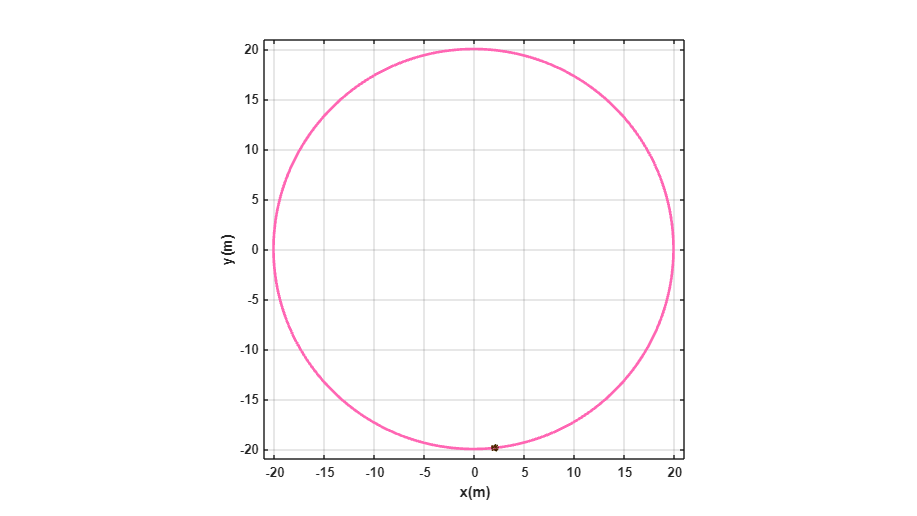

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'Color', [1 0.4 0.7],'lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se calculan las velocidades de las ruedas derecha (`wr`) y izquierda (`wl`) utilizando las ecuaciones cinemáticas del robot diferencial, y se crean dos nuevas subgráficas. La primera muestra la velocidad de la rueda derecha, y la segunda, la velocidad de la rueda izquierda.

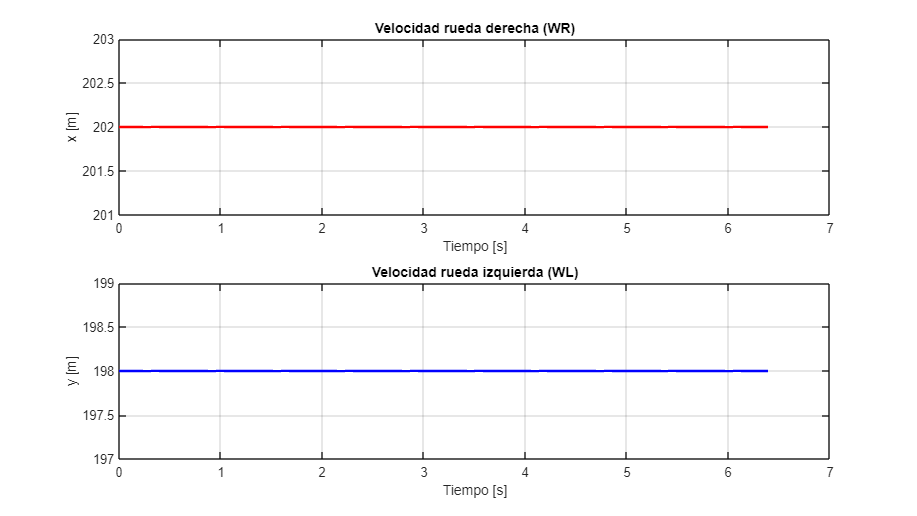

wr = (2*u + w*L) / (2*r);
wl = (2*u - w*L) / (2*r);

graph6 = figure;
set(graph6, 'position', sizeScreen);

subplot(2,1,1)
plot((0:N-1)*ts, wr, 'r', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('x [m]');
title('Velocidad rueda derecha (WR)');
grid on;

subplot(2,1,2)
plot((0:N-1)*ts, wl, 'b', 'LineWidth', 2);
xlabel('Tiempo [s]'); ylabel('y [m]');
title('Velocidad rueda izquierda (WL)');
grid on;